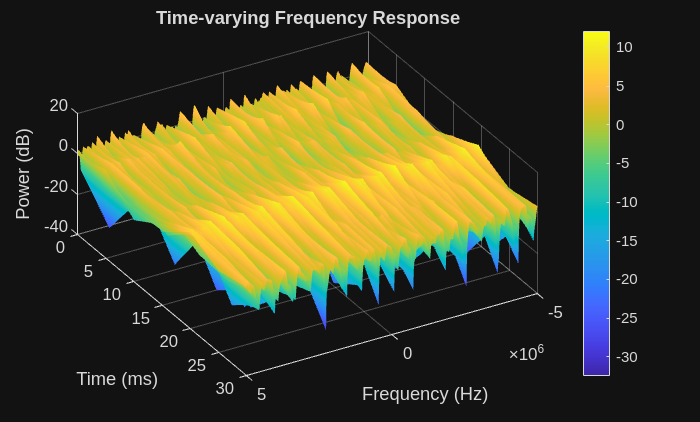

pg_db = [-2 0 -1 -6 -9 -14];
tau_mus = [0 1.8 3.5 5.7 8.1 12.3];
tau = tau_mus*1e-6;
pg = 10.^(pg_db/10);


%% PARAMETERS
Nfft = 2048;
fd = 90;                 % Doppler frequency (Hz)
Tsnap = 5e-3;            % 5 ms snapshot spacing
num_snapshots = 7;       % 0 to 30 ms

Ts = Tsnap;               % sampling time (adjust if given)
% Ts = 5e-4;

Taus = 1e-7;

%% NORMALIZE PDP
pg = pg / sum(pg);       % ensure sum σ_i^2 = 1

L = length(pg);
delay_idx = round(tau / Taus);

%% INITIAL CHANNEL GENERATION
h = zeros(1, Nfft);

N0 = 32;
N = num_snapshots;

h = zeros([N, Nfft]);
for i = 1:L
    h(:,delay_idx(i)+1) = sqrt(pg(i))*utils.SOS(fd, Ts, N0, N); 
end

%% 3D PLOT
time_axis = (0:Tsnap:(num_snapshots-1)*Tsnap)*1000; % ms
freq_axis = (-Nfft/2:Nfft/2-1)/(Taus*Nfft);     % frequency axis in Hz

[Freq, Time] = meshgrid(freq_axis, time_axis);

H = fftshift(fft(h, [], 2), 2);
H_all = 10*log10(abs(H).^2 + 1e-12); % avoid log(0)

figure;
surf(Freq, Time, H_all);
xlabel('Frequency (Hz)');
ylabel('Time (ms)');
zlabel('Power (dB)');
title('Time-varying Frequency Response');
shading interp;
view(135, 30);
colorbar;

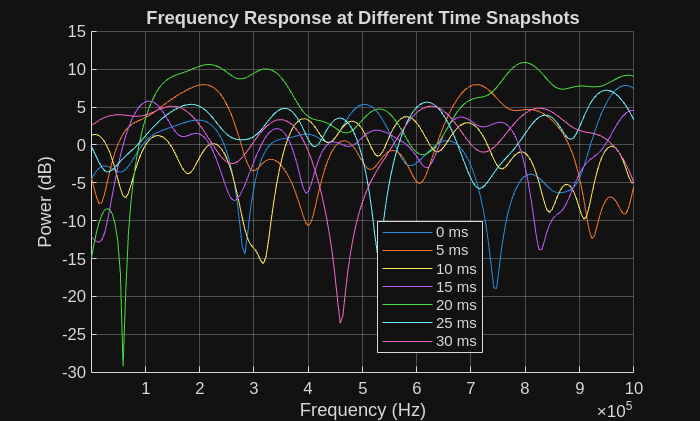

size(H_all);
figure;
hold on;

labels = strings(1, size(H_all,1)); % preallocate

for i = 1:size(H_all,1)
    plot(freq_axis, H_all(i,:));
    labels(i) = sprintf('%d ms', (i-1)*5); % actual time
end

legend(labels, 'Location', 'best');

xlabel('Frequency (Hz)');
ylabel('Power (dB)');
title('Frequency Response at Different Time Snapshots');
grid on;
xlim([1e-6 1e6])